# Modelo SEIRS

**Universidad eafit**

**Segundo Semestre 2024**

**Sistemas lineales**

**Carlos M. Veléz S.**

**Luis M. Martinez G.**

**Sebastian A. Amaya C.**

## 1. El Modelo SIERS

El modelo SEIRS, una piedra angular de la epidemiología, divide las poblaciones en compartimentos susceptibles (S), expuestos (E), infecciosas (I), recuperadas (R) y nuevamente susceptibles (S), lo que proporciona un enfoque estructurado para estudiar la dinámica de transmisión de enfermedades. A través de ecuaciones diferenciales, rastrea el movimiento de los individuos entre estos compartimentos a lo largo del tiempo, lo que refleja las transiciones de la susceptibilidad a la exposición, la infección y, en última instancia, la recuperación o la susceptibilidad nuevamente.

La versatilidad de este modelo se extiende a diversas aplicaciones, incluida la predicción de la propagación de enfermedades, la evaluación de estrategias de intervención y la optimización de la asignación de recursos durante los brotes. Al simular diferentes escenarios, los investigadores y los responsables de la formulación de políticas pueden anticipar la trayectoria de las enfermedades infecciosas, evaluar la eficacia de las medidas de control y tomar decisiones informadas para mitigar su impacto en la salud pública.

Su marco matemático proporciona información sobre las tasas de transmisión, los períodos de latencia y la dinámica de la inmunidad, lo que permite a las partes interesadas implementar medidas proactivas y gestionar eficazmente los brotes de enfermedades dentro de las poblaciones.

### **1.1. Descripción del modelo**

La mayoría de las descripciones matemáticas de la dinámica poblacional de las enfermedades infecciosas se basan en la capacidad de dividir la población en compartimentos discretos que no se superponen para así estudiar el flujo de los individuos a través de las diferentes clasificaciones. Para este Modelo se estudian 4 compartimientos:

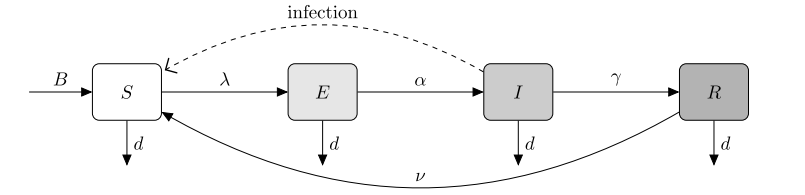

#### **Figura 1**

La figura 1 nos brinda un "esquema" del modelo y de la interacción de entre las poblaciones del modelo de esta práctica, es importante hacer clara ciertas consideraciones del modelo, primero, tomando una visión centrada en el patógeno, categorizamos al huésped (persona) por su estado con respecto al patógeno, Como las siglas del modelo indican los compartimientos en los que se divide la población son:

- Susceptibles(S):Individuos que no han sido infectados por la enfermedad y que pueden contraerla si entran en contacto con personas infectadas

- Infecciosas(I):Individuos actualmente infectados con la enfermedad y que pueden transmitirla a otros susceptibles.

- Recuperados(R):Individuos que han sido infectados previamente, pero ya se han recuperado de la enfermedad. Son inmunes y pueden volver a contraer la enfermedad.

- Expuestos(E): Individuos que han sido infectados con una enfermedad, pero que aún no son contagiosos.

- Población total (N): es la suma de todas las poblaciones anteriores

Además, podemos observar que se considera una población aislada y que la enfermedad modelada no es mortal, es decir la única entrada de nuevos integrantes es mediante nacimientos  y la única salida es mediante muerte por causas ajenas al patógeno, en la siguiente sección se explicara con mayor detalle la dinámica del modelo.

### **1.2. VARIABLES Y PARÁMETROS DEL MODELO**

Se puede observar que se usan varios parámetros para regular el flujo entre las diferentes poblaciones, a continuación se da una descripción de estas:

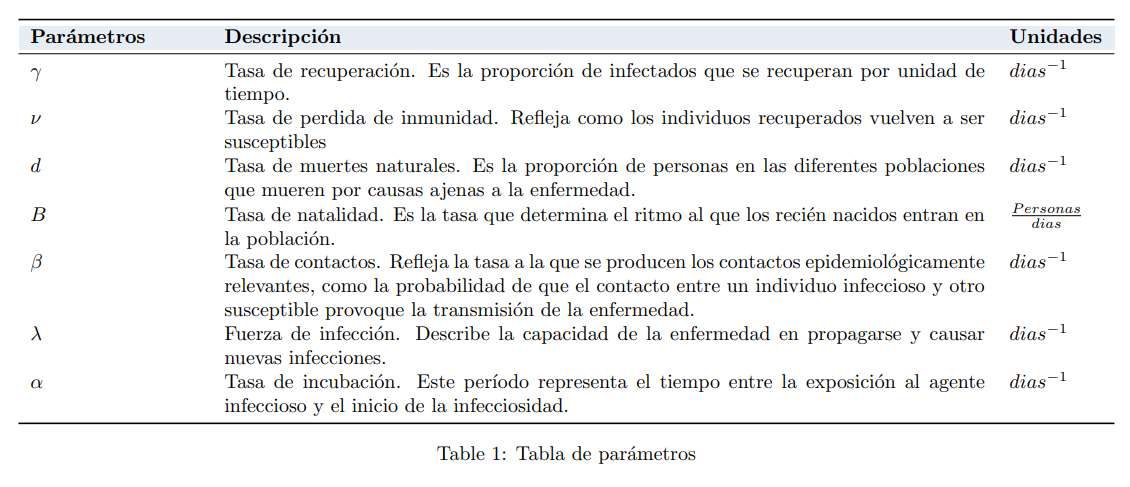

#### **Figura 2**

### **1.3 Ecuaciones del modelo**

Considerando la clasificación de la población previamente establecida, las ecuaciones no lineales del modelo se pueden describir de la siguiente manera:

La población susceptible `(S)` varía con el tiempo `(t)`, aumentando con la llegada de recién nacidos `(B) `y los recuperados que pierden su inmunidad `(νR)`, y disminuyendo con los susceptibles que son infectados `(-λS)` y los que han muerto por causas naturales `(-dS)`.


$$\frac{\mathrm{dS} }{\mathrm{d} t}=B+\nu R-\lambda S-dS$$
  

La población expuesta `(E)` varía con el tiempo `(t)`, incrementando con los susceptibles que han sido infectados `(λS)` y disminuyendo con los individuos expuestos que incuban la enfermedad (se vuelven infecciosos) `(-αE)` y los expuestos que han fallecido por causas naturales `(-dE)`.


$$\frac{\mathrm{d} E}{\mathrm{d} t}=\lambda S -\alpha E-dE$$
  

La población infectada `(I)` varía con el tiempo `(t)`, aumentando con los individuos expuestos que incuban la enfermedad (se vuelven infecciosos) `(αE)`, y reduciendo con aquellos infectados que se han recuperado `(-γI) `o han fallecido por causas naturales `(-dI)`.


$$\frac{\mathrm{d} I }{\mathrm{d} t}=\alpha E - \gamma I-dI$$
 

La población recuperada `(R)` varía con el tiempo `(t)`, incrementando con los individuos infectados que se han recuperado `(γI)` y reduciendo con aquellos recuperados que pierden su inmunidad y se vuelven susceptibles de nuevo `(-νR)` y los recuperados que han fallecido por causas naturales `(-dR)`.


$$\frac{\mathrm{d} R }{\mathrm{d} t}= \gamma I-\nu R-dR$$


Debido a que el tamaño de nuestra población es variable, el valor de la fuerza de infección **(λ) **se actualiza constantemente


$$\lambda=\frac{\beta I}{N}$$


El modelo completo se compone de las siguientes 5 ecuaciones:

**(1) **$\frac{\mathrm{dS} }{\mathrm{d} t}=B+\nu R-\lambda S-dS$            

**(2) **$\frac{\mathrm{d} E}{\mathrm{d} t}=\lambda S -\alpha E-dE$                

**(3) **$\frac{\mathrm{d} I }{\mathrm{d} t}=\alpha E - \gamma I-dI$                 

**(4) **$\frac{\mathrm{d} R }{\mathrm{d} t}= \gamma I-\nu R-dR$                  

**(5) **$\lambda=\frac{\beta I}{N}$                                

### **1.4 hipótesis**

A continuación se plantean hipótesis de las estructuras encontradas en el proceso de identificación del sistema:

- Dada la naturaleza no lineal del modelo SEIRS, es posible que los modelos lineales básicos como el ARX o el OE no capturen completamente todas las dinámicas del sistema, especialmente en presencia de ruido. Esto podria afectar los resultados obtenidos que usen como base estas estructuras.

- Se espera que la inclusión de ruido en los datos afecte el rendimiento de los modelos, favoreciendo aquellos con estructuras más complejas, como los modelos Box-Jenkins (BJ), debido a su capacidad para manejar datos ruidosos.

- Se espera que la identificación produzca modelos de orden 4, ya que el sistema base tiene este grado. Un modelo de orden inferior podría no capturar adecuadamente la dinámica del sistema, mientras que uno de orden superior podría sobreajustar los datos. 

- Se anticipa que el Método del error de predicción, utilizando el algoritmo de gradiente descendente, funcione correctamente con un modelo ARX 441, dado que el modelo base es de orden 4 y no presenta retardos.

## 2. Métodos

En esta sección de métodos, se proporcionará una explicación de como se realiza la verificación del sistema en Simulink. Se describirá  el proceso de realización de cada prueba en Simulink, desde la configuración hasta la interpretación de los resultados, ofreciendo una visión general del enfoque metodológico utilizado en este estudio. Además, se explicara como se realizara un ejercicio de identificación del sistema generando datos de la salida de la población infectada con ruido (variaciones), esto se hace con el objetivo de simular como sería una identificación del sistema en el campo.

### 2.1 MODELO VERIFICADO DEL SISTEMA EN SIMULINK

Se Realiza la verificación del modelo al recrear la figura 3 de  [1] que representa el comportamiento del modelo SIERS, para cumplir este objetivo se realiza la simulación con parámetros que se enlistaran próximamente y se compara la simulación con la gráfica de referencia.

- ***β***=0.2

- `ν`=0.001

- ***α***=0.1

- `γ`=0.1

- `d`=0.0001

- `B`=0.0001

### **2.2 Resumen de los pasos para la Identificación**

El proceso se centra en la identificación de una estructura de modelo adecuada para representar el sistema. Los pasos son los siguientes:

- **Introducción de Entrada Artificial:** Dado que el modelo SEIRS no cuenta con entradas naturales, se añade una entrada artificial modificando el parámetro β(t), que regula la tasa de transmisión del sistema. La entrada artificial se aplica en Simulink para realizar las simulaciones correspondientes.

- **Análisis de Linealidad y Selección del Punto de Operación:** Se utiliza una entrada escalera con valores de u = 0:0.1:0.8 . Para cada entrada escalón, se captura el valor en el que se estabiliza el modelo. Estos valores se grafican contra los valores de entrada, lo que resulta en las **curvas de linealidad**. A partir de este análisis, se selecciona un punto de operación y un rango linealidad.

- **Selección del Periodo de Muestreo:** Usando una entrada escalón, se analiza la respuesta temporal del sistema para identificar datos importantes para la seleccion del periodo de muestreo como el tiempo y el punto de estabilizacion, y el tiempo de crecimeinto. El periodo de muestreo se selecciona asegurando que sea lo suficientemente pequeño para captar las dinámicas del sistema, este se ecoge siguiendo las reglas vistas en clase $ \left ( \frac{Tr}{10}<Ts<\frac{Tr}{2}  \right )$.

- **Generación de Datos con Ruido:** Se introduce ruido blanco aditivo en la salida del modelo SEIRS para simular variaciones en los datos experimentales. Para la identificación del modelo, se utilizan una **secuencia PRBS (Pseudo Random Binary Sequence)**, generadas alrededor de un punto de operación y se mantiene dentro de un **rango de linealidad**. Esto permite obtener datos experimentales representativos del comportamiento del sistema.

-  **Identificación de Estructuras de Modelo: **Se evalúan diversas estructuras de modelos, como ARX, ARMAX, OE y BJ, utilizando la System Identification Toolbox de MATLAB. La identificación se lleva a cabo con los datos generados a partir de la secuencia PRBS. Los parámetros del modelo se ajustan para determinar cuál de las estructuras seleccionadas representa de manera más precisa la dinámica del sistema.

- **Selección de Modelos Candidatos:** Los modelos se eligen mediante el análisis de residuos y el ajuste a los datos experimentales. Se verifica que los residuos no estén correlacionados, lo que sugiere un buen ajuste. 

- **Validación del Modelo:** Los modelos seleccionados se validan utilizando entradas escalón y senoidales. Se comparan las respuestas simuladas del modelo con las respuestas del sistema original dentro del rango de linealidad, observando si el modelo puede replicar adecuadamente el comportamiento dinámico del sistema dentro del rango de linealidad.

- **Análisis de Polos y Ceros:** Se analizan los polos y ceros del modelo seleccionado para evaluar sus características de estabilidad.

- **Optimización del Modelo:** Se selecciona el modelo ARX o OE con el mejor rendimiento basado en el análisis del paso 6. Luego, se optimizan los parámetros utilizando un algoritmo de gradiente descendente para minimizar el error cuadrático medio entre las salidas simuladas y los datos experimentales, buscando un ajuste más preciso.

## 3. Resultados

dir_modelo = "SEIRS_2_verificacion.slx";

### **3.1. Verificación de Código**

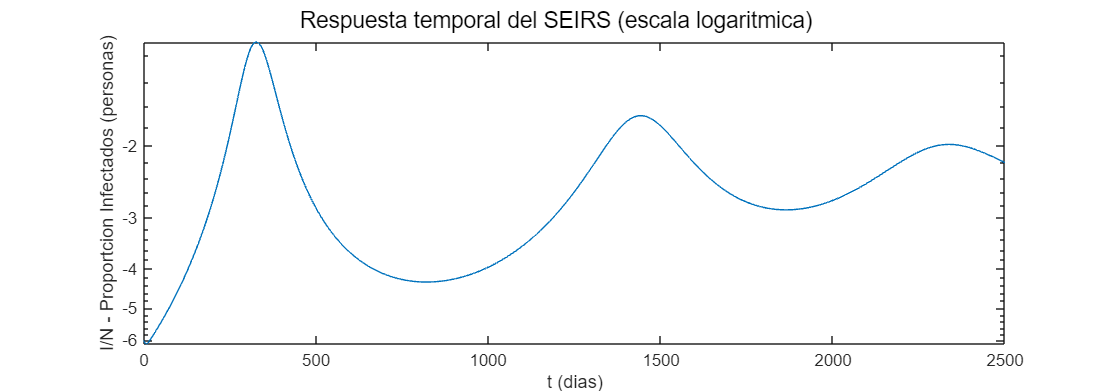

T=2500; 
x=zeros(1,6);
x(1)=0.0001; %B
x(2)=0.0001; %d
x(3)=0.1; %alpha_
x(4)=0.1; %gamma_
x(5)=0.2; %beta_
x(6)=0.001; %nu_
%N0_=[1-1e-6 1e-6 0 0]; 
beta_U=timetable(seconds(0),0);
simulacion_1_verificacion=sim(dir_modelo);
tiempo=simulacion_1_verificacion.tout;
infectados=simulacion_1_verificacion.infectados.signals.values;

h1 = figure;
subplot(1,1,1), plot(tiempo,infectados), xlabel('t (dias)'), ylabel('I/N - Proportcion Infectados (personas)')
set(h1,'Units','normalized','Position',[0 0 0.8 0.5]);
yscale log
sgtitle('Respuesta temporal del SEIRS (escala logaritmica)')

### **3.2. Linealización del modelo**

#### **3.2.1 Linealización experimental**

I=0:0.05:0.8;
T=10000;
var_init=zeros(1,6);
var_init(1)=0.0001; %B
var_init(2)=0.0001; %d
var_init(3)=0.1; %alpha_
var_init(4)=0.1; %gamma_
var_init(5)=0.2; %beta_dos;
var_init(6)=0.001; %nu_

dir_modelo = "SEIRS_Test.slx";
data_S=[];
data_E=[];
data_I=[];
data_R=[];
for i=I
    u=i;
    prueba_sim=sim(dir_modelo);
    data_S=[data_S,prueba_sim.S.signals.values(end)];
    data_E=[data_E,prueba_sim.E.signals.values(end)];
    data_I=[data_I,prueba_sim.I.signals.values(end)];
    data_R=[data_R,prueba_sim.R.signals.values(end)];
end

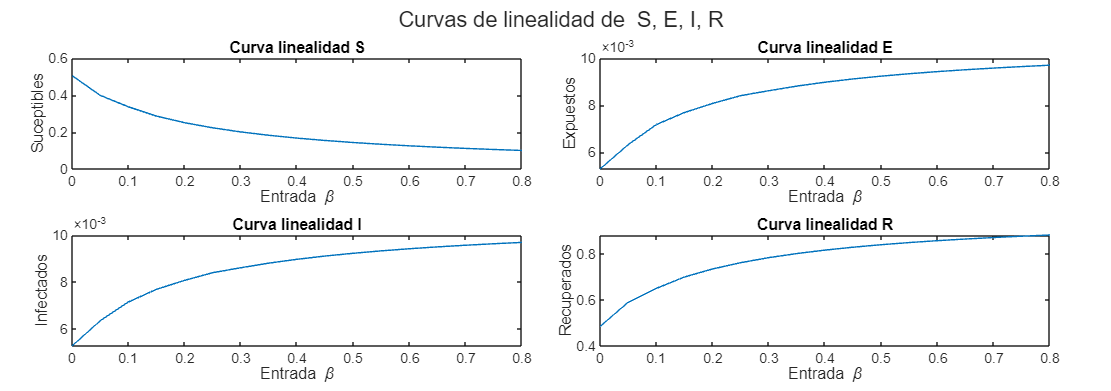

tiledlayout(2,2,'TileSpacing','compact','Padding','compact');


nexttile
plot(I, data_S),ylabel('Suceptibles');xlabel('Entrada \beta');title('Curva linealidad S');

nexttile
plot(I, data_E),ylabel('Expuestos');xlabel('Entrada \beta');title('Curva linealidad E');

nexttile
plot(I, data_I),ylabel('Infectados');xlabel('Entrada \beta');title('Curva linealidad I');

nexttile
plot(I, data_R),ylabel('Recuperados');xlabel('Entrada \beta');title('Curva linealidad R');
sgtitle('Curvas de linealidad de  S, E, I, R');

### 3.3. Punto de muestreo

dir_modelo = "SEIRS_Test.slx";
u=0.6; %punto de operacion escogido
T=7000;
Sim_Punto_M=sim(dir_modelo);


S_M=Sim_Punto_M.S.signals.values;
E_M=Sim_Punto_M.E.signals.values;
I_M=Sim_Punto_M.I.signals.values;
R_M=Sim_Punto_M.R.signals.values;
t_M=Sim_Punto_M.I.time;
Funcion_yss= @(x,m) (x(end)-x(1))*m+x(1);

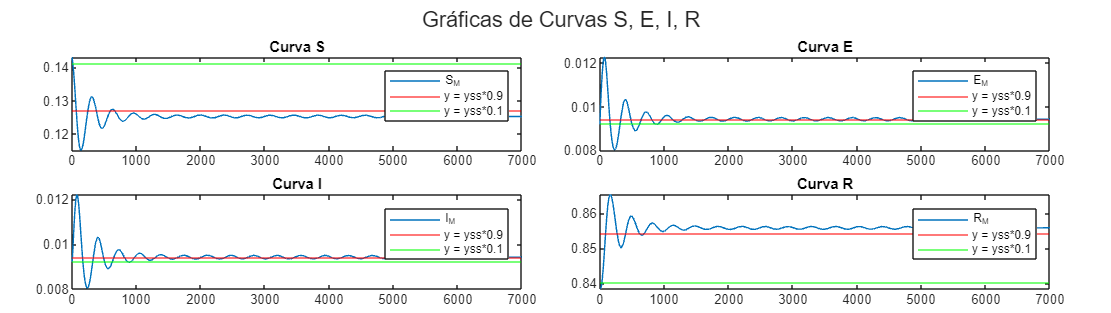

figure('Units', 'normalized', 'Position', [0, 0, 1, 0.5]);
tiledlayout(2,2,"Padding","compact","TileSpacing","compact");

nexttile
plot(t_M,S_M),yline(Funcion_yss(S_M,0.9), 'r-');yline(Funcion_yss(S_M,0.1), 'green-');title('Curva S');legend('S_M', 'y = yss*0.9', 'y = yss*0.1', 'Location', 'northeast');

nexttile
plot(t_M,E_M),yline(Funcion_yss(E_M,0.9), 'r-');yline(Funcion_yss(E_M,0.1), 'green-');title('Curva E');legend('E_M', 'y = yss*0.9', 'y = yss*0.1', 'Location', 'northeast');

nexttile
plot(t_M,I_M),yline(Funcion_yss(I_M,0.9), 'r-');yline(Funcion_yss(I_M,0.1), 'green-');title('Curva I');legend('I_M', 'y = yss*0.9', 'y = yss*0.1', 'Location', 'northeast');

nexttile
plot(t_M,R_M),yline(Funcion_yss(R_M,0.9), 'r-' );yline(Funcion_yss(R_M,0.1), 'green-');title('Curva R');legend('R_M', 'y = yss*0.9', 'y = yss*0.1', 'Location', 'northeast');

sgtitle('Gráficas de Curvas S, E, I, R');

syms tr ts
rango=tr/10<ts<tr/2

$$rango = \left(\frac{\mathrm{tr}}{10}<\mathrm{ts}\right)<\frac{\mathrm{tr}}{2}$$

rango=subs(rango,tr,int8(t_M(find(R_M<=Funcion_yss(R_M,0.9)*1.001 & R_M>=Funcion_yss(R_M,0.9)*0.999,1))))

$$rango = \left(\frac{89}{10}<\mathrm{ts}\right)<\frac{89}{2}$$

Seleccion_ts=ts==10

$$Seleccion\_ts = \mathrm{ts}=10$$

### **3.4 Generación de datos con ruido**

#### **3.4.1 verificación de ruido con entrada escalera**

T=18000;
Sim_ruido=sim("SEIRS_Ruido.slx");
S=Sim_ruido.S.signals.values;
E=Sim_ruido.E.signals.values;
I=Sim_ruido.I.signals.values;
R=Sim_ruido.R.signals.values;
t=Sim_ruido.I.time;

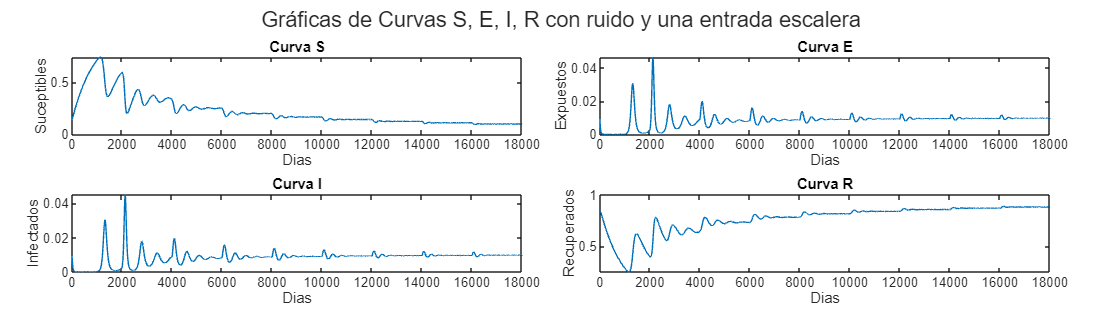

figure('Units', 'normalized', 'Position', [0, 0, 1, 0.5]);
tiledlayout(2,2,"Padding","compact","TileSpacing","compact");

nexttile,plot(t,S),xlabel('Dias');ylabel('Suceptibles');title('Curva S');

nexttile
plot(t,E),xlabel('Dias');ylabel('Expuestos');title('Curva E');

nexttile
plot(t,I),xlabel('Dias');ylabel('Infectados');title('Curva I');

nexttile
plot(t,R),xlabel('Dias');ylabel('Recuperados');title('Curva R');sgtitle('Gráficas de Curvas S, E, I, R con ruido y una entrada escalera');

#### **3.4.2 Generación de datos con una entrada PRBS**

T=20000;
var_init=zeros(1,6);
var_init(1)=0.0001; %B
var_init(2)=0.0001; %d
var_init(3)=0.1; %alpha_
var_init(4)=0.1; %gamma_
var_init(5)=0.2; %beta_dos;
var_init(6)=0.001; %nu_
Control_U=3;
time = (0:10:T)';
beta_U = timetable(seconds(time),zeros(numel(time),1));
beta_seno = timetable(seconds(time),zeros(numel(time),1));
Rango_PRBS=[0.5 0.7];
dir_modelo = "SEIRS_PRBS.slx";
Sim_Data=sim(dir_modelo);

Y=Sim_Data.I.signals.values;
U=Sim_Data.Entrada_U.signals.values;
t=Sim_Data.I.time;


#### **3.4.3 Generación de datos con una entrada escalón**

T=20000;
var_init=zeros(1,6);
var_init(1)=0.0001; %B
var_init(2)=0.0001; %d
var_init(3)=0.1; %alpha_
var_init(4)=0.1; %gamma_
var_init(5)=0.2; %beta_dos;
var_init(6)=0.001; %nu_
u=0.6;
Control_U=1;
time = (0:10:T)';
beta_U = timetable(seconds(time),(time>=2500)*0.1+0.6);
beta_seno = timetable(seconds(time),zeros(numel(time),1));
dir_modelo = "SEIRS_PRBS.slx";
Sim_Data_Escalon=sim(dir_modelo);

Infectados_Escalon=Sim_Data_Escalon.I.signals.values;
Entrada_Escalon=Sim_Data_Escalon.Entrada_U.signals.values;
t_entrada=Sim_Data_Escalon.Entrada_U.time;
t_escalon=Sim_Data_Escalon.I.time;
Y_Escalon=Infectados_Escalon;
U_Escalon=Entrada_Escalon;

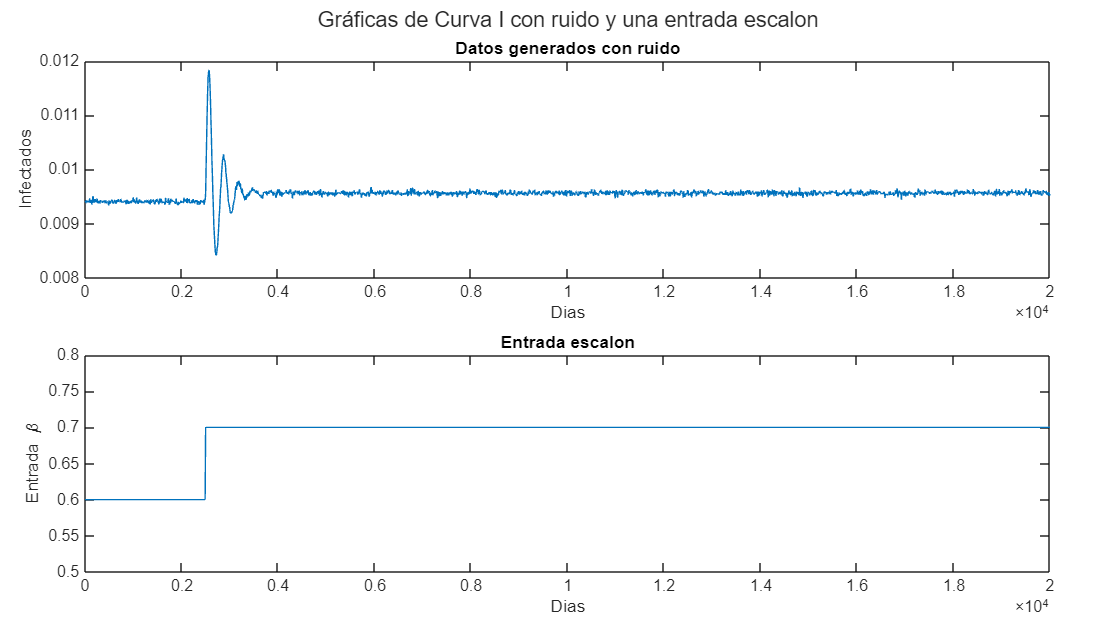

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);

tiledlayout(2,1,"Padding","compact","TileSpacing","compact");

nexttile,plot(t_escalon,Infectados_Escalon),xlabel('Dias');ylabel('Infectados');title('Datos generados con ruido');

nexttile
plot(t_entrada,Entrada_Escalon),ylim([0.5 0.8]);xlabel('Dias');ylabel('Entrada \beta');title('Entrada escalon');sgtitle('Gráficas de Curva I con ruido y una entrada escalon');

#### **3.4.6 Generación de datos con una entrada  **sinusoidal

T=20000;
var_init=zeros(1,6);
var_init(1)=0.0001; %B
var_init(2)=0.0001; %d
var_init(3)=0.1; %alpha_
var_init(4)=0.1; %gamma_
var_init(5)=0.2; %beta_dos;
var_init(6)=0.001; %nu_
u=0.6;
Control_U=2;
time = (0:10:T)';
beta_U =timetable(seconds(time),zeros(numel(time),1));
beta_seno=timetable(seconds(time),-sin(time*2*pi/5000)*0.1 +0.6);
dir_modelo = "SEIRS_PRBS.slx";
Sim_Data_Escalon=sim(dir_modelo);

Infectados_Seno=Sim_Data_Escalon.I.signals.values;
Entrada_Seno=Sim_Data_Escalon.Entrada_U.signals.values;
t_entrada=Sim_Data_Escalon.Entrada_U.time;
t_escalon=Sim_Data_Escalon.I.time;
Y_Seno=Infectados_Seno;
U_Seno=Entrada_Seno;

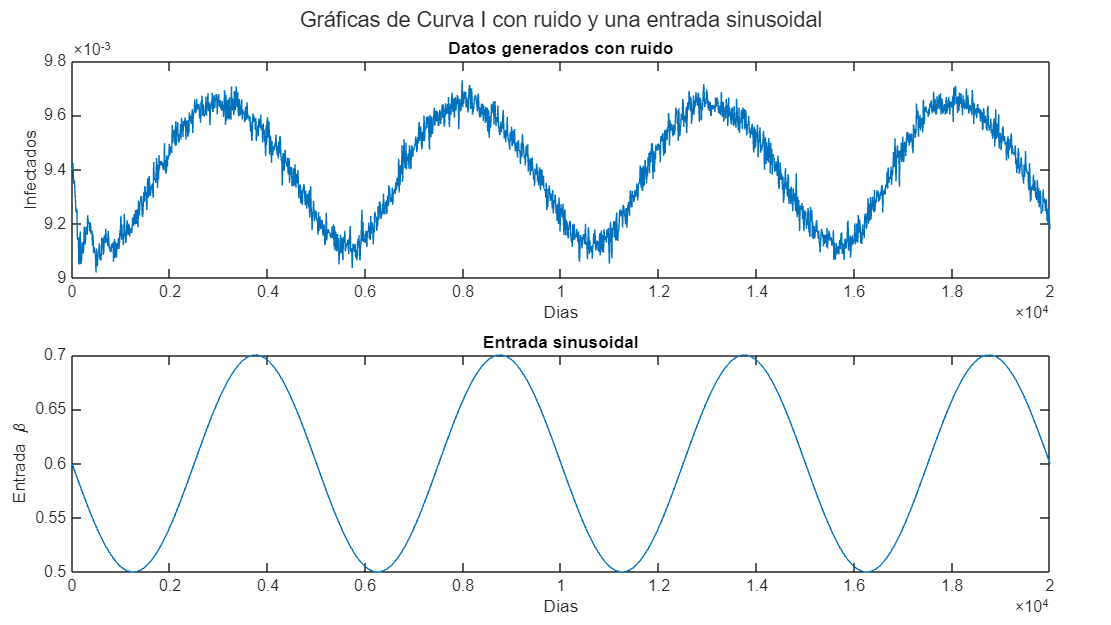

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);

tiledlayout(2,1,"Padding","compact","TileSpacing","compact");

nexttile
plot(t_escalon,Infectados_Seno),xlabel('Dias');ylabel('Infectados');title('Datos generados con ruido');

nexttile
plot(t_entrada,Entrada_Seno),xlabel('Dias');ylabel('Entrada \beta');title('Entrada sinusoidal');sgtitle('Gráficas de Curva I con ruido y una entrada sinusoidal');

### **3.5 Gráfico de selección de retardo**

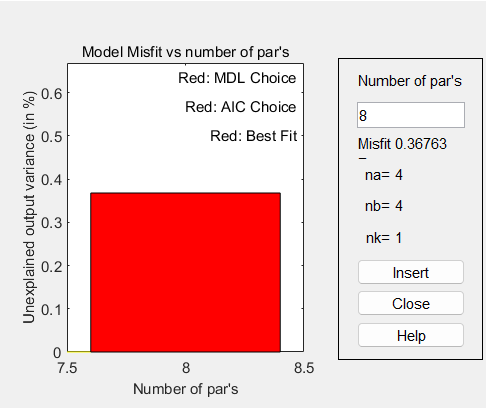

### 3.6 Gráfico de la función de coste para varias estructuras.

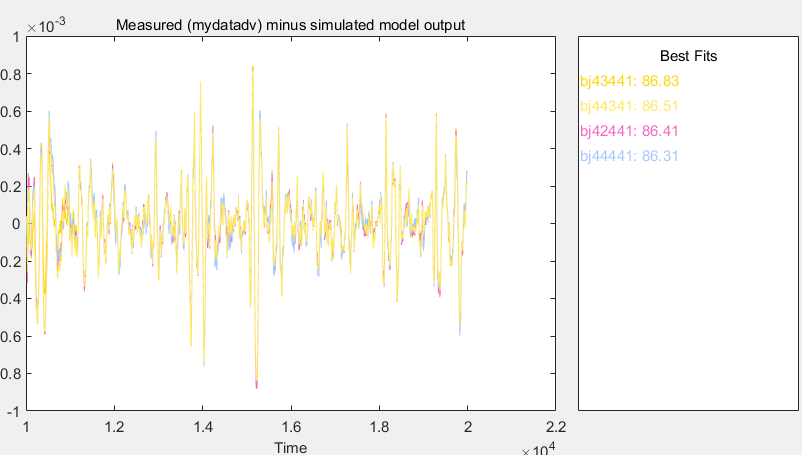

### 3.7 Gráfico de validación de las salidas temporales

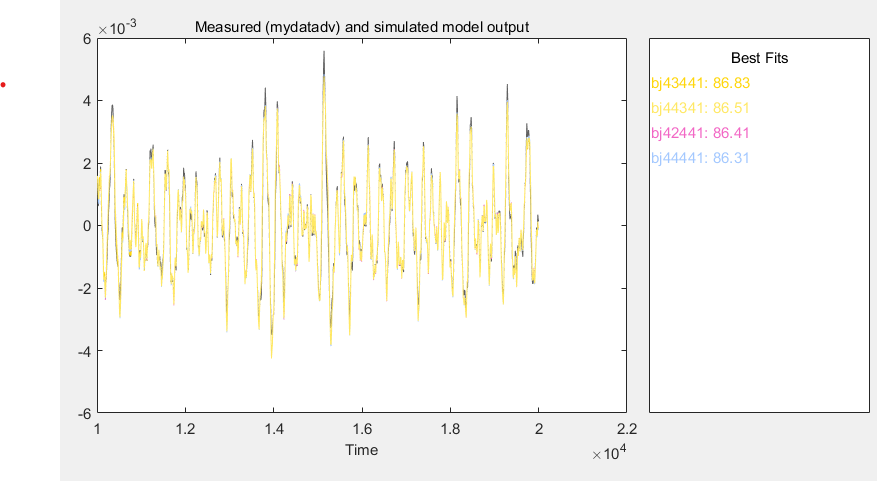

### **3.8 Gráfico de validación residual**

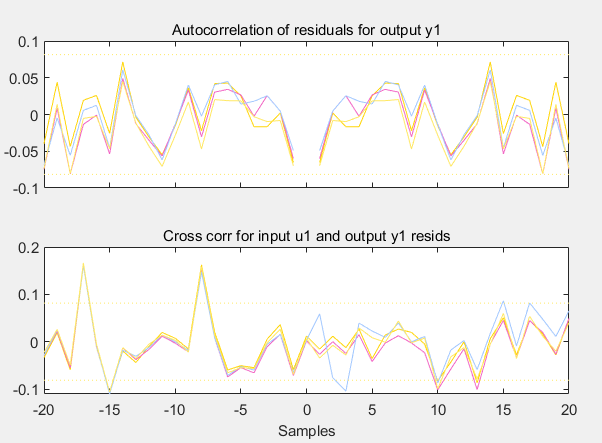

### **3.9 Gráfico de validación con la entrada escalón y las estructuras más representativas.**

#### 3.9.1 Modelo BJ42441

load("bj42441.mat")
T=20000;
time = (0:10:T)';
u = timetable(seconds(time),(time>=2500)*0.1);
y_sim = lsim(bj42441, u.Var1);

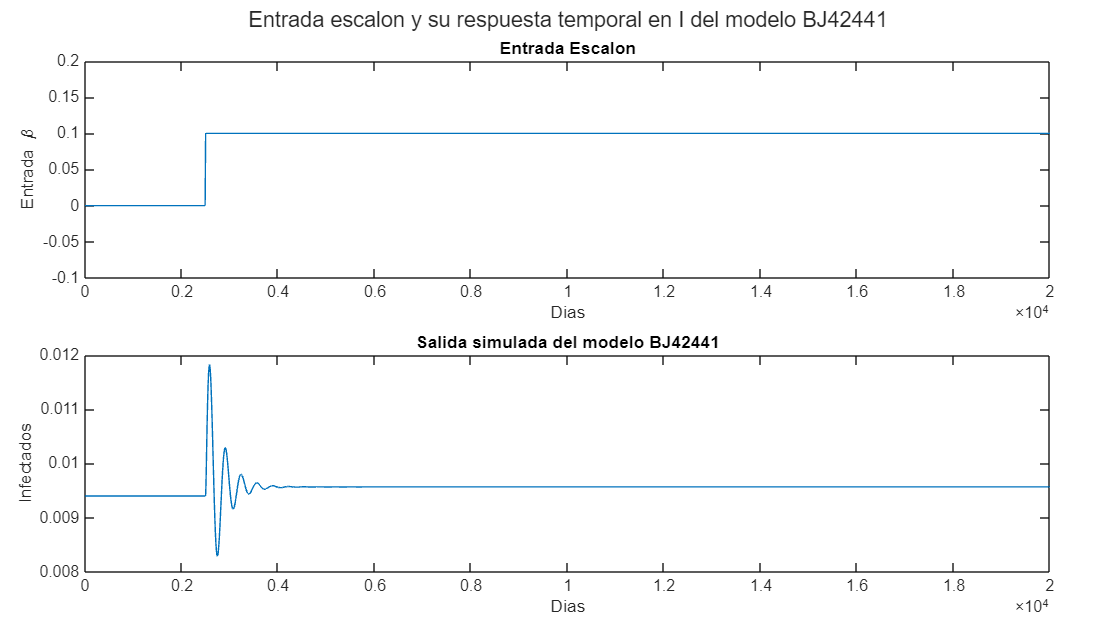

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);

tiledlayout(2,1,"Padding","compact","TileSpacing","compact");

nexttile
plot(t, u.Var1);xlabel('Dias');ylabel('Entrada \beta');title('Entrada Escalon');ylim([-0.1 0.2]);

y_sim_lin=y_sim+0.0094;

nexttile
plot(t, y_sim_lin);xlabel('Dias');ylabel('Infectados');title('Salida simulada del modelo BJ42441');

sgtitle('Entrada escalon y su respuesta temporal en I del modelo BJ42441');

#### 3.9.1 Modelo 

load("bj43441.mat")
T=20000;
time = (0:10:T)';
u = timetable(seconds(time),(time>=2500)*0.1);
y_sim = lsim(bj43441, u.Var1);

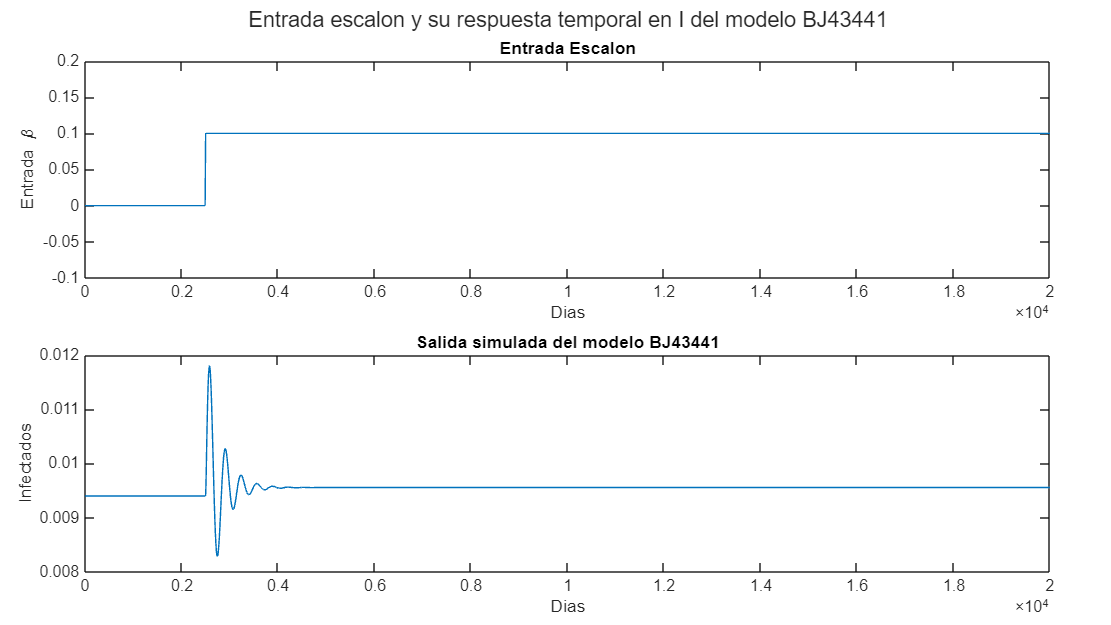

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);

tiledlayout(2,1,"Padding","compact","TileSpacing","compact");

nexttile
plot(t, u.Var1);xlabel('Dias');ylabel('Entrada \beta');title('Entrada Escalon');ylim([-0.1 0.2]);

y_sim_lin=y_sim+0.0094;

nexttile
plot(t, y_sim_lin);xlabel('Dias');ylabel('Infectados');title('Salida simulada del modelo BJ43441');

sgtitle('Entrada escalon y su respuesta temporal en I del modelo BJ43441');

### 3.10 Gráfico de validación con la entrada sinusoidal y las estructuras más representativas.

#### 3.10.1 Modelo BJ42441

T=20000;
time = (0:10:T)';
u=timetable(seconds(time),-sin(time*2*pi/5000)*0.1);
y_sim = lsim(bj42441, u.Var1);

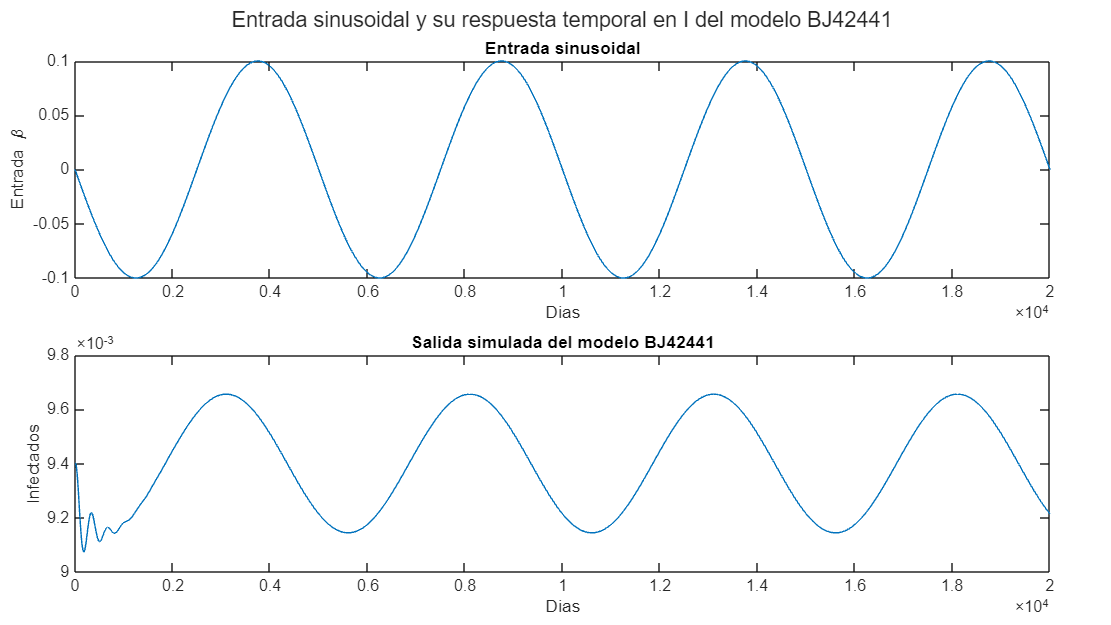

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);

tiledlayout(2,1,"Padding","compact","TileSpacing","compact");
nexttile
plot(t, u.Var1);xlabel('Dias');ylabel('Entrada \beta');title('Entrada sinusoidal');

y_sim_lin=y_sim+0.0094;

nexttile
plot(t, y_sim_lin);xlabel('Dias');ylabel('Infectados');title('Salida simulada del modelo BJ42441');

sgtitle('Entrada sinusoidal y su respuesta temporal en I del modelo BJ42441');

#### 3.10.2 Modelo BJ43441

T=20000;
time = (0:10:T)';
u=timetable(seconds(time),-sin(time*2*pi/5000)*0.1);
y_sim = lsim(bj43441, u.Var1);

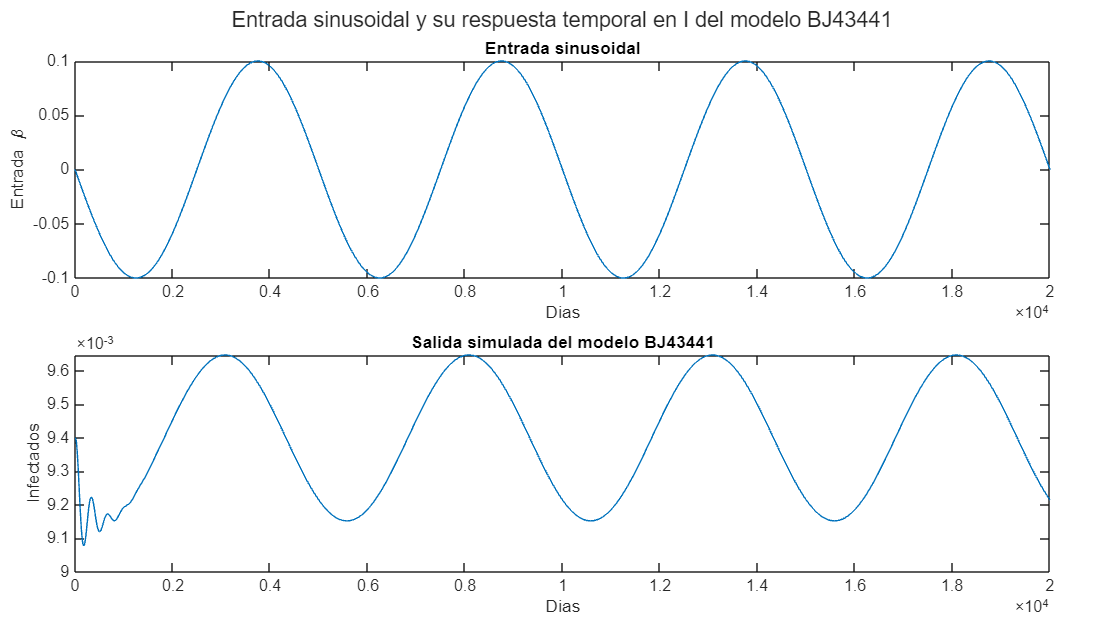

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);

tiledlayout(2,1,"Padding","compact","TileSpacing","compact");
nexttile
plot(t, u.Var1);xlabel('Dias');ylabel('Entrada \beta');title('Entrada sinusoidal');

y_sim_lin=y_sim+0.0094;

nexttile
plot(t, y_sim_lin);xlabel('Dias');ylabel('Infectados');title('Salida simulada del modelo BJ43441');

sgtitle('Entrada sinusoidal y su respuesta temporal en I del modelo BJ43441');

### 3.11 Mejor modelo con los intervalos de confianza de cada parámetro y el gráfico de polos y ceros.

El mejor modelo estimado, tiene una estructura  Box-Jenkins (BJ)43441:


$$y(t)= \frac{B(z)}{A(z)}u(t) +\frac{C(z)}{D(z)}e(t)$$



$$
   \[
   B(z) = 0.003 \, (\pm 0.00002) z^{-1} + 0.001 \, (\pm 0.0004) z^{-2} - 0.003 \, (\pm 0.0002) z^{-3} - 0.0015 \, (\pm 0.0002) z^{-4}
   \]$$



$$  \[
   A(z) = 1 \, (\pm 0.1) - 1.1 \, (\pm 0.1) z^{-1} - 0.6 \, (\pm 0.2) z^{-2} + 0.9 \, (\pm 0.1) z^{-3} - 0.1 \, (\pm 0.02) z^{-4}
   \]$$



$$\[
   C(z) = 1 \, (\pm 0.07) - 2.4 \, (\pm 0.1) z^{-1} + 1.8 \, (\pm 0.1) z^{-2} - 0.5 \, (\pm 0.06) z^{-3}
   \]$$



$$\[
   D(z) = 1 \, (\pm 0.05) - 3.5 \, (\pm 0.1) z^{-1} + 4.8 \, (\pm 0.1) z^{-2} - 3 \, (\pm 0.1) z^{-3} + 0.7 \, (\pm 0.04) z^{-4}
   \]$$


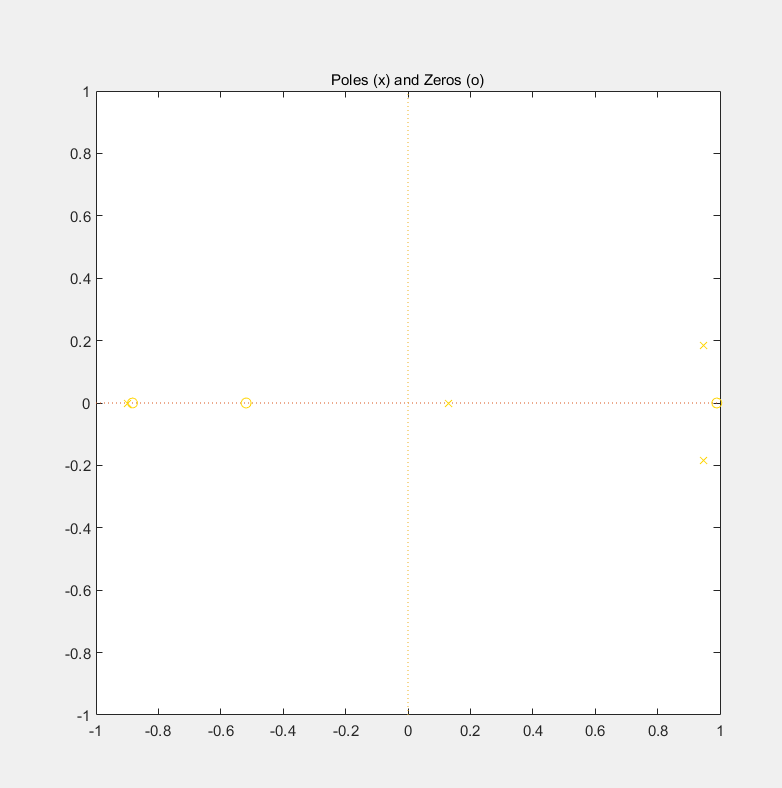

### 3.12 Pantallazo legible de la interfaz gráfica del System Identification Toolbox de MATLAB con todos los datos y resultados más representativos.

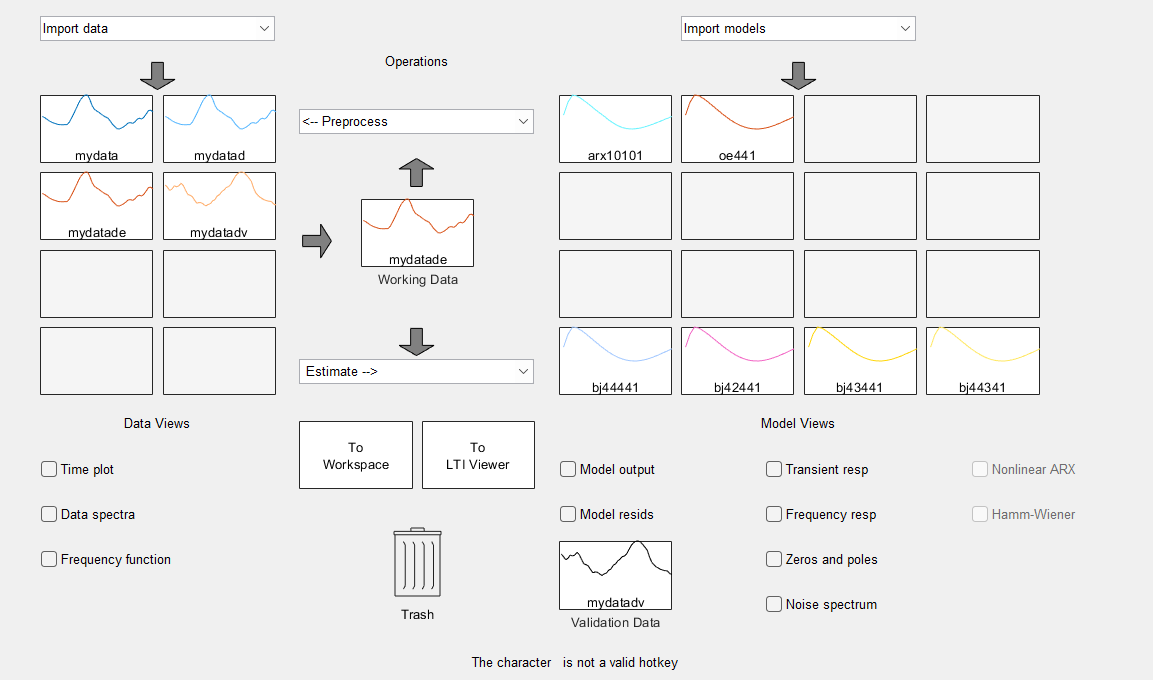

### **3.13 algoritmo gradiente descendente**

#### **3.13.1 opciones del método**

N = 2001;
M = 501;
alpha0 = 0.1;
b10 = 0.7;
b20 = 0.7;
b30 =0.7;
b40 = 0.7;
a10 = -0.5;
a20= 0.5;
a30= 0.5;
a40= -0.5;

#### **3.13.2 Modelo de tiempo discreto para la generación de datos**

b1 = 0.00328;
b2 = -4.607e-05;
b3 =-0.002043;
b4 = - 0.0007218;
a1 = -1.562;
a2= 0.3198; 
a3= 0.3165;
a4= - 0.01741;
Ts = 10;
Gd = tf([b1 b2 b3 b4],[1 a1 a2 a3 a4],'Ts',Ts);
t = (0:(N-1))'*10;

#### 3.13.3 Datos experimentales

% Entrada experimental tipo ruido blanco gaussiano
rng(1), u = randn(N,1);
% Salida experimental con una estructura OE
v = 0.2*randn(N,1);
rng(2), y = lsim(Gd,u,t) + v;

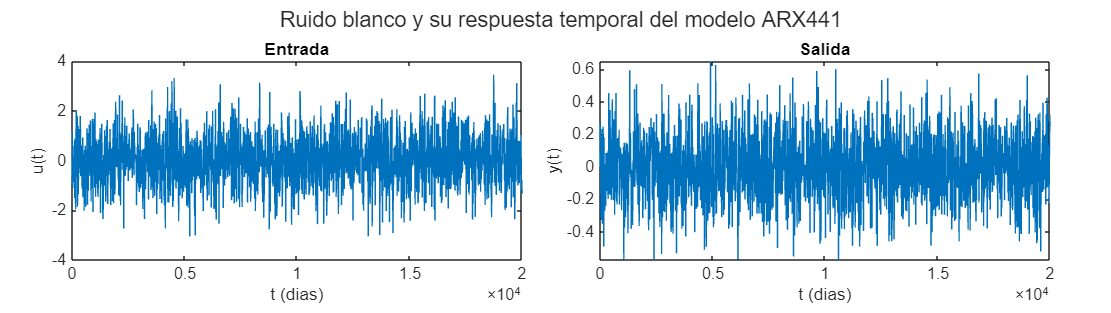


figure('Units','normalized','Position',[0 0 1 0.5])

tiledlayout(1,2,"Padding","compact","TileSpacing","compact");

nexttile, plot(t,u), xlabel('t (dias)'), ylabel('u(t)'), title('Entrada')

nexttile, plot(t,y), xlabel('t (dias)'), ylabel('y(t)'), title('Salida')

sgtitle('Ruido blanco y su respuesta temporal del modelo ARX441');

#### **3.13.4 Matrices con los datos de la estimación**

a = zeros(M,4); a(1,:) = [a10 a20 a30 a40];
b = zeros(M,4); b(1,:) = [b10 b20 b30 b40];
V = zeros(M,1);
res = zeros(N-4,1);

#### 3.13.5 Método numérico del gradiente descendente con modelo ARX441

% e = y - yest = Ay - Bu = (1+a1q^-1 + a2q^-2 + a3q^-3 + a4q^-4)y  - (b1q^-1 + b2q^-2 + b3q^-3 + b4q^-4)u
%   = y + a1 y(t-1) + a2y(t-2) + a3y(t-3) + a4y(t-4)  - b1u(t-1) - b2u(t-2)  - b3u(t-3) - b4u(t-4)
e = y(5:N) + a(1,1)*y(4:N-1)+a(1,2)*y(3:N-2)+a(1,3)*y(2:N-3)+a(1,4)*y(1:N-4)...
    - b(1,1)*u(4:N-1)-b(1,2)*u(3:N-2)-b(1,3)*u(2:N-3)-b(1,4)*u(1:N-4);
V(1,1) = e'*e/N;
for i=1:M-1
    DVa = (2/N)*[e'*y(4:N-1),e'*y(3:N-2),e'*y(2:N-3),e'*y(1:N-4)];
    DVb = -(2/N)*[e'*u(4:N-1),e'*u(3:N-2),e'*u(2:N-3),e'*u(1:N-4)];
    a(i+1,:) = a(i,:) - alpha0*DVa;
    b(i+1,:) = b(i,:) - alpha0*DVb;
    e = y(5:N) + a(i+1,1)*y(4:N-1)+a(i+1,2)*y(3:N-2)+a(i+1,3)*y(2:N-3)+a(i+1,4)*y(1:N-4) ...
        - b(i+1,1)*u(4:N-1)-b(i+1,2)*u(3:N-2)-b(i+1,3)*u(2:N-3)-b(i+1,4)*u(1:N-4);
    V(i+1) = e'*e/N;
end
res(:,1) = e;

#### 3.15.6 Gráfico de convergencia de los parámetros

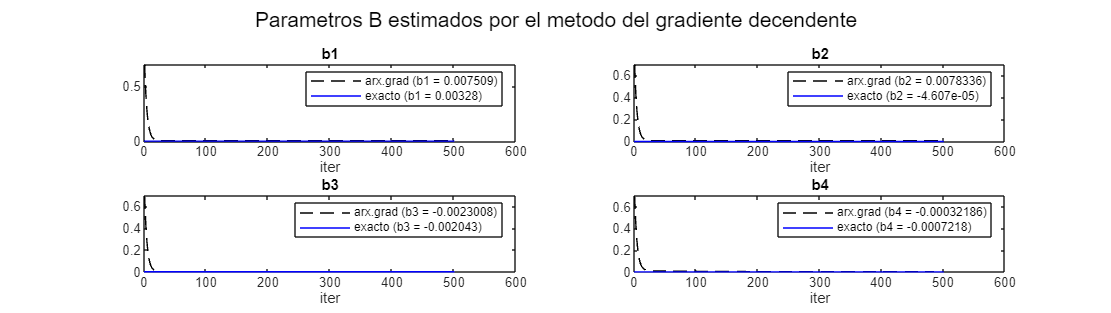

figure('Units','normalized','Position',[0 0 1 0.5])
t1 = 1:M;
subplot(2,2,1),plot(t1,b(:,1),'k--'),line([0 t1(end)],[b1 b1],'color','blue'),xlabel('iter'),title('b1'),legend({['arx.grad (b1 = ' num2str(b(M,1)) ')'],['exacto (b1 = ' num2str(b1) ')']})

subplot(2,2,2),plot(t1,b(:,2),'k--'),line([0 t1(end)],[b2 b2],'color','blue'),xlabel('iter'),title('b2'),legend({['arx.grad (b2 = ' num2str(b(M,2)) ')'],['exacto (b2 = ' num2str(b2) ')']})

subplot(2,2,3),plot(t1,b(:,3),'k--'),line([0 t1(end)],[b3 b3],'color','blue'),xlabel('iter'),title('b3'),legend({['arx.grad (b3 = ' num2str(b(M,3)) ')'],['exacto (b3 = ' num2str(b3) ')']})

subplot(2,2,4),plot(t1,b(:,4),'k--'),line([0 t1(end)],[b4 b4],'color','blue'),xlabel('iter'),title('b4'),legend({['arx.grad (b4 = ' num2str(b(M,4)) ')'],['exacto (b4 = ' num2str(b4) ')']})
sgtitle('Parametros B estimados por el metodo del gradiente decendente');

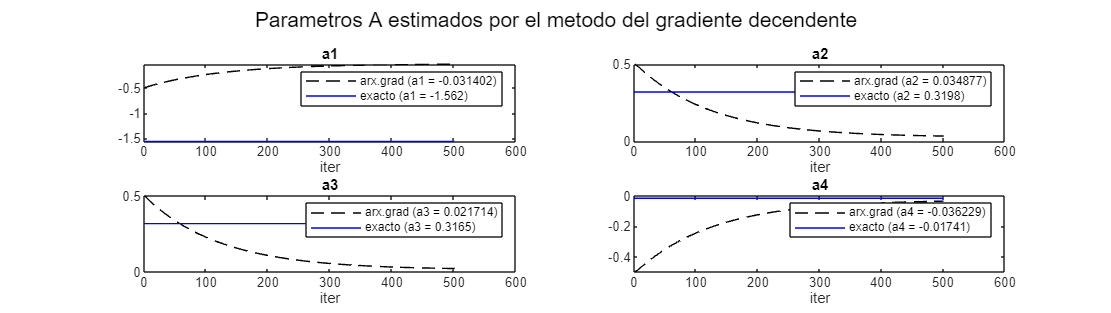

figure('Units','normalized','Position',[0 0 1 0.5])

t1 = 1:M;

subplot(2,2,1)
plot(t1,a(:,1),'k--'),line([0 t1(end)],[a1 a1],'color','blue'),xlabel('iter'),title('a1'),legend({['arx.grad (a1 = ' num2str(a(M,1)) ')'],['exacto (a1 = ' num2str(a1) ')']})

subplot(2,2,2)
plot(t1,a(:,2),'k--'),line([0 t1(end)],[a2 a2],'color','blue'),xlabel('iter'),title('a2'),legend({['arx.grad (a2 = ' num2str(a(M,2)) ')'],['exacto (a2 = ' num2str(a2) ')']})

subplot(2,2,3)
plot(t1,a(:,3),'k--'),line([0 t1(end)],[a3 a3],'color','blue'),xlabel('iter'),title('a3'),legend({['arx.grad (a3 = ' num2str(a(M,3)) ')'],['exacto (a3 = ' num2str(a3) ')']})

subplot(2,2,4)
plot(t1,a(:,4),'k--'),line([0 t1(end)],[a4 a4],'color','blue'),xlabel('iter'),title('a4'),legend({['arx.grad (a4 = ' num2str(a(M,4)) ')'],['exacto (a4 = ' num2str(a4) ')']})

sgtitle('Parametros A estimados por el metodo del gradiente decendente');

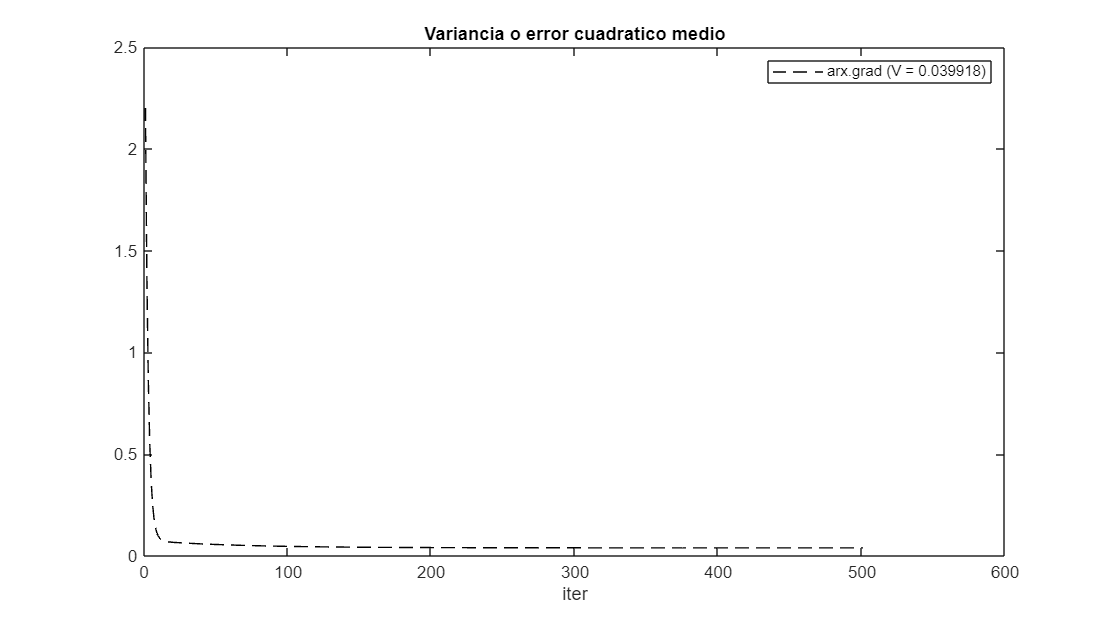

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);

plot(t1,V(:,1),'k--');xlabel('iter');title('Variancia o error cuadratico medio');legend({['arx.grad (V = ' num2str(V(M,1)) ')']})

#### 3.15.7 Gráficos de la prueba de blancura

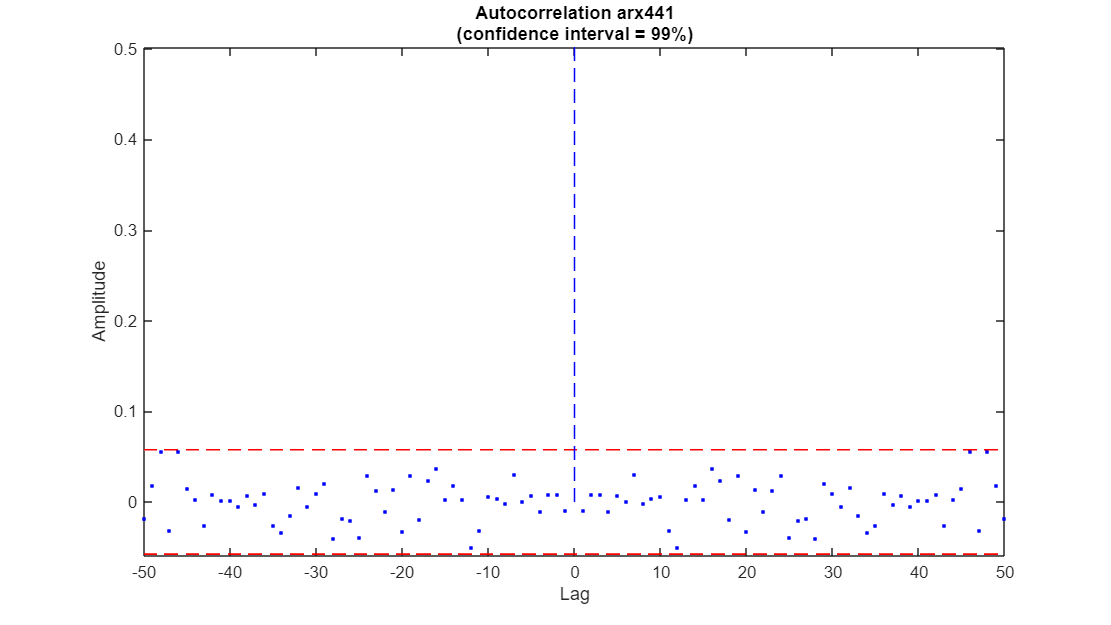

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);

lagmax = 50;
[R,lags,conf] = whiteness_test(res(:,1),lagmax);
plot(lags,R,'b.')
line([lags(1) lags(end)],conf*[1 1],'color','red','linestyle','--','linewidth',1)
line([lags(1) lags(end)],-conf*[1 1],'color','red','linestyle','--','linewidth',1)
line([0 0],[0 max(R)],'color','blue','linestyle','--','linewidth',0.1)
xlabel('Lag')
ylabel('Amplitude')
title({'Autocorrelation arx441';'(confidence interval = 99%)'})
ylim([ min([R,-conf])-0.002    max([R(1:ceil(lagmax)),conf,0.5])+0.002 ])

## 4. DISCUSIÓN

En esta sección, se abordan detalladamente los resultados obtenidos en la sección anterior, proporcionando un análisis exhaustivo para cada uno de ellos. Se exploran las implicaciones, patrones emergentes y cualquier correlación significativa que pueda arrojar luz sobre los hallazgos, contribuyendo así a una comprensión más completa y matizada de los datos recopilados**.**

### **4.1 Verificación del Código **

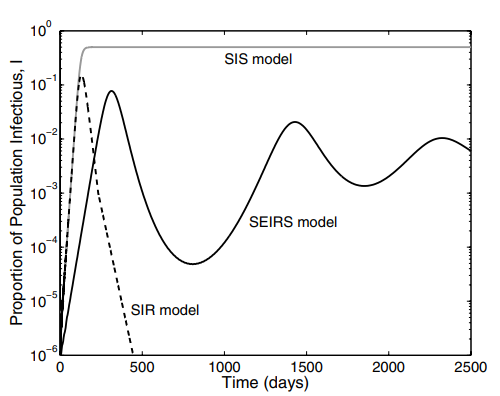

#### Figura 3

La figura 3 nos muestra el comportamiento esperado de la población de infectados en el modelo SEIRS (Curva negra) al comparar esta gráfica con la generada por el modelo en la sección 3.1 podemos observar que ambas curvas se corresponden, con esto podemos verificar que el modelo implementado se comporta de forma correcta.

### 4.2 Curvas de Linealidad

Las curvas obtenidas nos muestras que el sistema no presenta un comportamiento lineal, sin embargo, es facil extraer un rango de linealidad alrededor de u=0.6, por lo tanto se escoge como rango de linealidad u=0.6$\pm$1, con este rango se establecen las condiciones para el resto del analisis.

### 4.3 Punto de muestreo

Tomando del rango de linealidad y el punto de operacion escogidos en la seccion anterior se realizo una nueva simulacion, como se observa en las curvas, se puede tomar una estimacion para el tiempo de crecimiento, en este caso fue alrededor t=89, siguiendo lo visto en clase se selecciona un tiempo de muestro Ts=10. el cual utilizamos para la digitalizacion del modelo.

### 4.4 Generacion de datos con ruido

Para una generacion apropiada de los datos nos apoyamos de nuevo en el rango de linealidad escogido

#### 4.4.1 Entrada PRBS

Se genera una entrada PRBS para los datos que se usaran para la identificacion del sistema, esto se debe ya que la entrada PRBS es fuertemente exitada lo que beneficia la identificacion del modelo en los pasos siguientes.

### 4.5 Seleccion del retardo

Se utilizó el toolbox de identificación de sistemas para proponer un modelo autorregresivo con entradas exógenas (ARX), fijando los parámetros na y nb en 2. El parámetro de retardo nk se varió entre 1 y 100. El análisis resultó en un valor óptimo de nk=1, lo que indica que el sistema de origen de los datos no parece presentar retardos significativos en su respuesta.

### 4.6 Grafico de Funcion De Coste

El gráfico de residuos sugiere que el modelo se ajusta razonablemente bien a los datos, con los puntos de datos distribuidos de manera aleatoria alrededor de la línea cero. Aunque hay algunos valores atípicos, no afectan significativamente la tendencia general.  Además, no hay una correlación fuerte entre los residuos y el tiempo, lo que sugiere que el modelo captura adecuadamente las dinámicas dependientes del tiempo. 

### 4.7 Grafico de validacion de salidas temporales

Los modelos presentan un alto porcentaje de ajuste, lo que indica que las estructuras seleccionadas se alinean con los datos experimentales y son apropiadas para representar la dinámica del sistema analizado. Es importante destacar que el modelo Box-Jenkins mostró resultados satisfactorios al usar parametros nb y nf(na) iguales a 4, lo que puede indicar que el sistema original es de orden 4. 

### 4.8 grafico de validacion residual

Los gráficos de autocorrelación y correlación cruzada indican que el modelo identificado está razonablemente bien especificado, ya que los residuos no exhiben autocorrelación ni correlación cruzada significativa con la entrada. Sin embargo, el ligero pico en la función de autocorrelación en el rezago 1 sugiere la necesidad de una investigación adicional, como analizar los residuos en el dominio del tiempo o considerar una estructura de modelo alternativa. En general, el análisis indica que el modelo captura eficazmente la relación entre los datos de entrada y salida, pero es posible que se deban abordar problemas menores para mejorar su rendimiento.

### **4.9 Gráficos de validación con la entrada escalón y sinusoidal de las estructuras más representativas.**

Al analizar los datos experimentales de la entrada escalón en comparación con la respuesta temporal de los modelos lineales bj42441 y bj43441 dentro del rango de linealidad, se concluye que estos modelos reflejan adecuadamente el comportamiento de los datos experimentales para dicha entrada. Este patrón también se observa con entradas sinusoidales, lo que sugiere que los modelos son adecuados para representar la dinámica del sistema en diferentes tipos de entrada siempre y cuando esten en el rango de linealidad.

### 4.10 Mejor Modelo

Como se muestra en los análisis anteriores, la estructura más adecuada para estimar el modelo es la BJ43441. Sin embargo, el gráfico de polos y ceros sugiere que el sistema podría ser representado por un modelo de orden menor. Esta observación genera inconsistencias con el conocimiento previo del sistema, ya que se sabe que el sistema original es de orden 4. Es importante evaluar si la simplificación del modelo BJ43441 es adecuada o si se necesita ajustar la estructura del modelo para reflejar mejor el comportamiento del sistema.

### 4.11 Método del error de predicción con el algoritmo del gradiente descendente

El algoritmo de descenso de gradiente converge de manera efectiva para la mayoría de los parámetros, demostrando su capacidad para estimar el modelo con precisión. La blancura de los residuos, según lo muestra la función de autocorrelación, sugiere que el modelo captura las dinámicas subyacentes del sistema sin factores significativos no modelados. Además, la varianza decreciente del error cuadrático medio (MSE) durante el proceso de optimización confirma la convergencia del algoritmo hacia una solución estable, lo que indica un rendimiento confiable del modelo.

Sin embargo, un análisis más detallado revela inestabilidad en las estimaciones de los parámetros **a1**, **a2** y **a3**, lo que indica falta de convergencia. Esta desviación sugiere que, si bien la mayoría de los parámetros están bien ajustados, estos coeficientes específicos presentan desafíos para el algoritmo, probablemente debido a la estructura del modelo o a características particulares de los datos. Ajustes adicionales, como modificar la estructura del modelo o aplicar técnicas de estimación alternativas, podrían mejorar la estabilidad de estos parámetros.

## 5. Referencias

- [1]       K. Rock, S. Brand, J. Moir, and M. J. Keeling, ‘Dynamics of infectious diseases’, Reports on Progress in Physics, vol. 77, no. 2, p. 026602, Jan. 2014.

- [2]  O. N. Bjørnstad, K. Shea, M. Krzywinski, and N. Altman, ‘The SEIRS model for infectious disease dynamics’, Nature Methods, vol. 17, no. 6, pp. 557–558, Jun. 2020.

- [3]  T. Tomé and M. de Oliveira, ‘Susceptible-infected-recovered and susceptible-exposed-infected models’, J. Phys. J. Phys. A: Math. Theor, vol. 16750, 03 2011.

- [4]        Bill & Melinda Gates Foundation. “SEIR and SEIRS Models — HIV Model Documentation.” *Docs.idmod.org*, docs.idmod.org/projects/emod-hiv/en/latest/model-seir.html. Accessed 14 Apr. 2024.